% =========================================================================
% SCRIPT analyse_assembly_results5parfor.mlx:
%  EXTRACT_BEST_K_FROM_RESULTS + GRAPHIQUES + SUCCESSRATE
% Objectif : Trouver les meilleurs K, extraire le Success Rate, et faire les graphes
% =========================================================================

clear; clc; close all

%% 1. PARAMÈTRES ET CHEMINS
dossier_mere = "E:\Data\Aurelie\analysis\Final\assembly\nocues\";

nbtop = 5; %nb K à sortir
k_start = 4;

%% 2. POIDS DES CRITÈRES POUR LE SCORE GLOBAL
weight_silhouette = 0;
weight_recall = 0.5;
weight_cell_specificity = 0.3;
weight_sce_purity = 0.20;

%% 3. RECHERCHE DE TOUS LES FICHIERS RESULTS.MAT
% fprintf('Recherche des fichiers results.mat...\n');
tous_les_fichiers = dir(fullfile(dossier_mere, '**', 'results.mat'));

if isempty(tous_les_fichiers)
    error('Aucun fichier results.mat trouvé.');
end
sessions_autorisees = {'411582_230320_plane0', '411582_230320_plane1', '443669_220614_plane0', '443669_220614_plane1', ...
    '443695_220728_plane0', '443695_220809_plane1','444113_220927_plane1', '444113_220928_plane1', ...
    '444119_220919_plane0', '444119_220919_plane1','444152_221129_plane0', '444152_221129_plane1', ...
    '444175_221121_plane0', '444175_221121_plane1', '444175_221125_plane0', '444175_221125_plane1', ...
    '446178_11062025_plane0', '446178_11062025_plane1', '446198_12062025_plane0','446178_14062025_plane0',...
'446178_14062025_plane1'...
};

% Filtrage vectoriel direct et réécriture de la variable
tous_les_fichiers = tous_les_fichiers(contains({tous_les_fichiers.folder}, sessions_autorisees));


% fprintf('%d fichiers trouvés. Analyse en cours...\n\n', length(tous_les_fichiers));

%% 4. EXTRACTION ET CALCULS DES MÉTRIQUES (PARALLÉLISÉ)
% fprintf('Démarrage du pool parallèle...\n');
% Vérifie si un pool est ouvert, sinon en ouvre un
poolobj = gcp('nocreate');
if isempty(poolobj)
    parpool;
end

N_fichiers = length(tous_les_fichiers);

% Pré-allocation des variables pour le parfor
temp_sessionName     = cell(N_fichiers, 1);
temp_safeSessionName = cell(N_fichiers, 1);
temp_k               = NaN(N_fichiers, 1);
temp_silhouette      = NaN(N_fichiers, 1);
temp_sce_recall      = NaN(N_fichiers, 1);
temp_cell_spec_inter = NaN(N_fichiers, 1);
temp_cell_spec_global= NaN(N_fichiers, 1);
temp_sce_purity      = NaN(N_fichiers, 1);
temp_success_rate    = NaN(N_fichiers, 1);
temp_paths           = cell(N_fichiers, 1);

% Configuration de la barre de progression pour parfor
h_wait = waitbar(0, 'Extraction des données (Parallel)...', 'Name', 'Progression');
D = parallel.pool.DataQueue;
afterEach(D, @(~) updateWaitbar(h_wait, N_fichiers));

fprintf('Début de l''extraction en parallèle...\n');

Début de l'extraction en parallèle...



parfor i = 1:N_fichiers
    % --- Initialisation locale ---
    matFilePath = fullfile(tous_les_fichiers(i).folder, tous_les_fichiers(i).name);
    parts = strsplit(tous_les_fichiers(i).folder, filesep);
    
    if length(parts) < 2
        send(D, i); continue;
    end
    
    kFolderName = parts{end};
    sessName = parts{end-1};
    
    k_num_str = regexp(kFolderName, '\d+', 'match');
    if isempty(k_num_str)
        send(D, i); continue; 
    end
    
    c_k = str2double(k_num_str{1});
    if c_k < k_start
        send(D, i); continue;
    end

    % --- Chargement des données (.mat) ---
    try
        data = load(matFilePath, 'RasterRace', 'NRace', 'NRaceOK', 'mean_sClOK', 'assemblyortho');
    catch
        send(D, i); continue;
    end
    
    % 1. Silhouette
    if isfield(data, 'mean_sClOK') && isnumeric(data.mean_sClOK) && ~isnan(data.mean_sClOK)
        c_silhouette = data.mean_sClOK;
    else
        send(D, i); continue;
    end
    
    % 2. Recall
    if isfield(data, 'NRaceOK') && isfield(data, 'NRace') && data.NRace > 0
        c_sce_recall = (data.NRaceOK / data.NRace) * 100;
    else
        c_sce_recall = 0;
    end
    
    % 3. Specificity & Purity
    c_cell_spec_inter = NaN;
    c_cell_spec_global = NaN;
    c_sce_purity = NaN;
    
    if isfield(data, 'assemblyortho') && ~isempty(data.assemblyortho) && isfield(data, 'RasterRace')
        nb_clusters = length(data.assemblyortho);
        nb_SCE = size(data.RasterRace, 2);
        
        if nb_clusters > 0 && nb_SCE > 0
            participation_SCE = zeros(nb_clusters, nb_SCE);
            for c = 1:nb_clusters
                cellules_c = data.assemblyortho{c};
                if ~isempty(cellules_c)
                    participation_SCE(c, :) = sum(data.RasterRace(cellules_c, :), 1);
                end
            end
            
            [val_max, SCE_labels] = max(participation_SCE, [], 1);
            SCE_labels(val_max == 0) = 0;
            
            cell_spec_inter_array = NaN(1, nb_clusters);
            cell_spec_global_array = NaN(1, nb_clusters);
            sce_purity_array = NaN(1, nb_clusters);
            
            for c = 1:nb_clusters
                cellules_du_cluster = data.assemblyortho{c};
                idx_SCE_du_cluster = (SCE_labels == c);
                
                if sum(idx_SCE_du_cluster) > 0 && ~isempty(cellules_du_cluster)
                    tirs_in_box = sum(data.RasterRace(cellules_du_cluster, idx_SCE_du_cluster), 'all');
                    
                    tirs_totaux_colonne = sum(data.RasterRace(:, idx_SCE_du_cluster), 'all');
                    if tirs_totaux_colonne > 0
                        sce_purity_array(c) = tirs_in_box / tirs_totaux_colonne;
                    end
                    
                    idx_SCE_valides = (SCE_labels > 0);
                    tirs_totaux_ligne_inter = sum(data.RasterRace(cellules_du_cluster, idx_SCE_valides), 'all');
                    if tirs_totaux_ligne_inter > 0
                        cell_spec_inter_array(c) = tirs_in_box / tirs_totaux_ligne_inter;
                    end
                    
                    tirs_totaux_ligne_global = sum(data.RasterRace(cellules_du_cluster, :), 'all');
                    if tirs_totaux_ligne_global > 0
                        cell_spec_global_array(c) = tirs_in_box / tirs_totaux_ligne_global;
                    end
                end
            end
            c_cell_spec_inter = mean(cell_spec_inter_array, 'omitnan');
            c_cell_spec_global = mean(cell_spec_global_array, 'omitnan');
            c_sce_purity = mean(sce_purity_array, 'omitnan');
        end
    end
    
    % 4. Lecture du Brainbow (Success Rate)
    chemin_brainbow = fullfile(tous_les_fichiers(i).folder, 'brainbow.mat');
    c_success_rate = NaN;
    if isfile(chemin_brainbow)
        try
            donnees_brainbow = load(chemin_brainbow, 'successrate');
            if isfield(donnees_brainbow, 'successrate')
                c_success_rate = donnees_brainbow.successrate;
            end
        catch
        end
    end
    
    % --- Enregistrement dans les tableaux temporaires ---
    if ~isnan(c_cell_spec_inter)
        temp_sessionName{i} = sessName;
        temp_safeSessionName{i} = matlab.lang.makeValidName(sessName);
        temp_k(i) = c_k;
        temp_silhouette(i) = c_silhouette;
        temp_sce_recall(i) = c_sce_recall;
        temp_cell_spec_inter(i) = c_cell_spec_inter;
        temp_cell_spec_global(i) = c_cell_spec_global;
        temp_sce_purity(i) = c_sce_purity;
        temp_success_rate(i) = c_success_rate;
        temp_paths{i} = tous_les_fichiers(i).folder;
    end
    
    send(D, i); % Met à jour la barre de progression
end
close(h_wait);

% --- Regroupement rapide des résultats dans la structure SessionsData ---
SessionsData = struct();
for i = 1:N_fichiers
    safeName = temp_safeSessionName{i};
    if ~isempty(safeName)
        if ~isfield(SessionsData, safeName)
            SessionsData.(safeName).OriginalName = temp_sessionName{i};
            SessionsData.(safeName).K = [];
            SessionsData.(safeName).Silh = [];
            SessionsData.(safeName).Recall = [];
            SessionsData.(safeName).CellSpecInter = [];
            SessionsData.(safeName).CellSpecGlobal = [];
            SessionsData.(safeName).SCEPurity = [];
            SessionsData.(safeName).SuccessRate = [];
            SessionsData.(safeName).Paths = {};
            SessionsData.(safeName).Scores = [];
        end
        
        SessionsData.(safeName).K(end+1) = temp_k(i);
        SessionsData.(safeName).Silh(end+1) = temp_silhouette(i);
        SessionsData.(safeName).Recall(end+1) = temp_sce_recall(i);
        SessionsData.(safeName).CellSpecInter(end+1) = temp_cell_spec_inter(i);
        SessionsData.(safeName).CellSpecGlobal(end+1) = temp_cell_spec_global(i);
        SessionsData.(safeName).SCEPurity(end+1) = temp_sce_purity(i);
        SessionsData.(safeName).SuccessRate(end+1) = temp_success_rate(i);
        SessionsData.(safeName).Paths{end+1} = temp_paths{i};
    end
end

%% 5. CALCUL DES SCORES ET PRÉPARATION DE LA TABLE EXCEL
sessionFields = fieldnames(SessionsData);
fprintf('--------------------------------------------------\n');

--------------------------------------------------



Excel_Session = {};
Excel_Rang = [];
Excel_K = [];
Excel_Score = [];
Excel_Silh = [];
Excel_Recall = [];
Excel_CellSpecInter = [];
Excel_CellSpecGlobal = [];
Excel_SCEPurity = [];
Excel_SuccessRate = []; 
Excel_Path = {};

for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) < 2, continue; end
    
    % 1. Silhouette : De [-1, 1] vers [0, 1]
    norm_sil = (sess.Silh + 1) / 2;
    % 2. Recall : Si sess.Recall est en % (0-100), on le divise par 100 pour l'avoir sur [0, 1]
    norm_rec = sess.Recall / 100;
    % 3. Specificity et Purity : Sont déjà des ratios entre 0 et 1
    norm_cell_spec = sess.CellSpecInter;
    norm_purity = sess.SCEPurity;
    
    % SECURITE : On s'assure qu'aucun score ne dépasse 1 ou ne descend sous 0
    norm_sil = max(0, min(1, norm_sil));
    norm_rec = max(0, min(1, norm_rec));
    norm_cell_spec = max(0, min(1, norm_cell_spec));
    norm_purity = max(0, min(1, norm_purity));

    % Calcul du Score Global
    Scores = (weight_silhouette * norm_sil) + ...
             (weight_recall * norm_rec) + ...
             (weight_cell_specificity * norm_cell_spec) + ...
             (weight_sce_purity * norm_purity);
             
    % SAUVEGARDE DES SCORES POUR LES GRAPHIQUES
    SessionsData.(sessionFields{s}).Scores = Scores;
    [sortedScores, sortIdx] = sort(Scores, 'descend');
    top_k = min(nbtop, length(sortIdx)); % Affichage/Export des N meilleurs
    
    fprintf('SESSION : %s\n', sess.OriginalName);
    for i = 1:top_k
        orig_idx = sortIdx(i);
        fprintf(' ⭐ #%d -> K = %d\n', i, sess.K(orig_idx));
        fprintf(' Chemin : %s\n', sess.Paths{orig_idx});
        fprintf(' (Score: %.2f | Silh: %.3f | Recall: %.1f%% | Cell Spec: %.3f | Succes: %.2f)\n', ...
            sortedScores(i), sess.Silh(orig_idx), sess.Recall(orig_idx), sess.CellSpecInter(orig_idx), sess.SuccessRate(orig_idx));
            
        Excel_Session{end+1, 1} = sess.OriginalName;
        Excel_Rang(end+1, 1) = i;
        Excel_K(end+1, 1) = sess.K(orig_idx);
        Excel_Score(end+1, 1) = sortedScores(i);
        Excel_Silh(end+1, 1) = sess.Silh(orig_idx);
        Excel_Recall(end+1, 1) = sess.Recall(orig_idx);
        Excel_CellSpecInter(end+1, 1) = sess.CellSpecInter(orig_idx);
        Excel_CellSpecGlobal(end+1, 1) = sess.CellSpecGlobal(orig_idx);
        Excel_SCEPurity(end+1, 1) = sess.SCEPurity(orig_idx);
        Excel_SuccessRate(end+1, 1) = sess.SuccessRate(orig_idx); 
        Excel_Path{end+1, 1} = sess.Paths{orig_idx};
    end
    fprintf('--------------------------------------------------\n');
end

SESSION : 411582_230320_plane0_26_07_18_09_38_08


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane0_26_07_18_09_38_08\k4


 (Score: 0.61 | Silh: 0.126 | Recall: 61.4% | Cell Spec: 0.678 | Succes: 33.33)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane0_26_07_18_09_38_08\k5


 (Score: 0.54 | Silh: 0.183 | Recall: 49.7% | Cell Spec: 0.693 | Succes: 66.67)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane0_26_07_18_09_38_08\k6


 (Score: 0.51 | Silh: 0.192 | Recall: 41.8% | Cell Spec: 0.699 | Succes: 66.67)


 ⭐ #4 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane0_26_07_18_09_38_08\k8


 (Score: 0.50 | Silh: 0.104 | Recall: 50.3% | Cell Spec: 0.544 | Succes: 20.00)


 ⭐ #5 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane0_26_07_18_09_38_08\k7


 (Score: 0.48 | Silh: 0.163 | Recall: 43.0% | Cell Spec: 0.609 | Succes: 25.00)


--------------------------------------------------


SESSION : 411582_230320_plane1_26_07_18_10_03_35


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane1_26_07_18_10_03_35\k4


 (Score: 0.59 | Silh: 0.209 | Recall: 55.2% | Cell Spec: 0.724 | Succes: 0.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane1_26_07_18_10_03_35\k5


 (Score: 0.56 | Silh: 0.217 | Recall: 49.8% | Cell Spec: 0.722 | Succes: 0.00)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane1_26_07_18_10_03_35\k6


 (Score: 0.56 | Silh: 0.218 | Recall: 48.9% | Cell Spec: 0.723 | Succes: 0.00)


 ⭐ #4 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane1_26_07_18_10_03_35\k8


 (Score: 0.56 | Silh: 0.126 | Recall: 59.4% | Cell Spec: 0.559 | Succes: 0.00)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\411582_230320_plane1_26_07_18_10_03_35\k9


 (Score: 0.54 | Silh: 0.127 | Recall: 55.6% | Cell Spec: 0.559 | Succes: 0.00)


--------------------------------------------------


SESSION : 443669_220614_plane0_26_07_18_10_30_15


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane0_26_07_18_10_30_15\k4


 (Score: 0.43 | Silh: 0.193 | Recall: 18.8% | Cell Spec: 0.827 | Succes: 50.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane0_26_07_18_10_30_15\k5


 (Score: 0.40 | Silh: 0.316 | Recall: 12.1% | Cell Spec: 0.822 | Succes: 50.00)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane0_26_07_18_10_30_15\k6


 (Score: 0.39 | Silh: 0.327 | Recall: 11.0% | Cell Spec: 0.819 | Succes: 100.00)


 ⭐ #4 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane0_26_07_18_10_30_15\k8


 (Score: 0.37 | Silh: 0.407 | Recall: 7.0% | Cell Spec: 0.819 | Succes: 50.00)


 ⭐ #5 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane0_26_07_18_10_30_15\k7


 (Score: 0.37 | Silh: 0.412 | Recall: 6.8% | Cell Spec: 0.821 | Succes: 50.00)


--------------------------------------------------


SESSION : 443669_220614_plane1_26_07_18_10_58_44


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane1_26_07_18_10_58_44\k4


 (Score: 0.54 | Silh: 0.054 | Recall: 43.1% | Cell Spec: 0.772 | Succes: 50.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane1_26_07_18_10_58_44\k5


 (Score: 0.50 | Silh: 0.054 | Recall: 47.5% | Cell Spec: 0.611 | Succes: 33.33)


 ⭐ #3 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane1_26_07_18_10_58_44\k8


 (Score: 0.45 | Silh: 0.089 | Recall: 46.6% | Cell Spec: 0.438 | Succes: 75.00)


 ⭐ #4 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane1_26_07_18_10_58_44\k9


 (Score: 0.43 | Silh: 0.093 | Recall: 42.3% | Cell Spec: 0.460 | Succes: 75.00)


 ⭐ #5 -> K = 10


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443669_220614_plane1_26_07_18_10_58_44\k10


 (Score: 0.42 | Silh: 0.090 | Recall: 44.2% | Cell Spec: 0.397 | Succes: 20.00)


--------------------------------------------------


SESSION : 443695_220728_plane0_26_07_18_12_20_48


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220728_plane0_26_07_18_12_20_48\k4


 (Score: 0.67 | Silh: 0.397 | Recall: 47.7% | Cell Spec: 0.941 | Succes: 0.00)


 ⭐ #2 -> K = 10


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220728_plane0_26_07_18_12_20_48\k10


 (Score: 0.64 | Silh: 0.359 | Recall: 52.0% | Cell Spec: 0.857 | Succes: 0.00)


 ⭐ #3 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220728_plane0_26_07_18_12_20_48\k5


 (Score: 0.58 | Silh: 0.458 | Recall: 29.5% | Cell Spec: 0.973 | Succes: 0.00)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220728_plane0_26_07_18_12_20_48\k7


 (Score: 0.58 | Silh: 0.481 | Recall: 29.2% | Cell Spec: 0.978 | Succes: 0.00)


 ⭐ #5 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220728_plane0_26_07_18_12_20_48\k6


 (Score: 0.58 | Silh: 0.471 | Recall: 28.9% | Cell Spec: 0.973 | Succes: 0.00)


--------------------------------------------------


SESSION : 443695_220809_plane1_26_07_18_12_34_51


 ⭐ #1 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220809_plane1_26_07_18_12_34_51\k6


 (Score: 0.62 | Silh: 0.252 | Recall: 47.7% | Cell Spec: 0.846 | Succes: 33.33)


 ⭐ #2 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220809_plane1_26_07_18_12_34_51\k4


 (Score: 0.61 | Silh: 0.285 | Recall: 38.0% | Cell Spec: 0.948 | Succes: 50.00)


 ⭐ #3 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220809_plane1_26_07_18_12_34_51\k5


 (Score: 0.57 | Silh: 0.323 | Recall: 31.0% | Cell Spec: 0.955 | Succes: 50.00)


 ⭐ #4 -> K = 10


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220809_plane1_26_07_18_12_34_51\k10


 (Score: 0.57 | Silh: 0.160 | Recall: 50.7% | Cell Spec: 0.694 | Succes: 60.00)


 ⭐ #5 -> K = 12


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\443695_220809_plane1_26_07_18_12_34_51\k12


 (Score: 0.55 | Silh: 0.180 | Recall: 45.8% | Cell Spec: 0.695 | Succes: 60.00)


--------------------------------------------------


SESSION : 444113_220927_plane1_26_07_18_12_52_08


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220927_plane1_26_07_18_12_52_08\k4


 (Score: 0.65 | Silh: 0.102 | Recall: 63.0% | Cell Spec: 0.783 | Succes: 33.33)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220927_plane1_26_07_18_12_52_08\k5


 (Score: 0.57 | Silh: 0.142 | Recall: 45.9% | Cell Spec: 0.782 | Succes: 0.00)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220927_plane1_26_07_18_12_52_08\k6


 (Score: 0.52 | Silh: 0.196 | Recall: 35.5% | Cell Spec: 0.788 | Succes: 33.33)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220927_plane1_26_07_18_12_52_08\k7


 (Score: 0.50 | Silh: 0.196 | Recall: 34.3% | Cell Spec: 0.794 | Succes: 33.33)


 ⭐ #5 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220927_plane1_26_07_18_12_52_08\k8


 (Score: 0.48 | Silh: 0.204 | Recall: 27.5% | Cell Spec: 0.789 | Succes: 33.33)


--------------------------------------------------


SESSION : 444113_220928_plane1_26_07_18_13_10_23


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220928_plane1_26_07_18_13_10_23\k4


 (Score: 0.61 | Silh: 0.249 | Recall: 39.5% | Cell Spec: 0.962 | Succes: 50.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220928_plane1_26_07_18_13_10_23\k5


 (Score: 0.58 | Silh: 0.257 | Recall: 32.8% | Cell Spec: 0.963 | Succes: 50.00)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220928_plane1_26_07_18_13_10_23\k6


 (Score: 0.53 | Silh: 0.298 | Recall: 24.3% | Cell Spec: 0.961 | Succes: 50.00)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220928_plane1_26_07_18_13_10_23\k7


 (Score: 0.48 | Silh: 0.170 | Recall: 24.9% | Cell Spec: 0.820 | Succes: 33.33)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444113_220928_plane1_26_07_18_13_10_23\k9


 (Score: 0.47 | Silh: 0.167 | Recall: 25.2% | Cell Spec: 0.808 | Succes: 33.33)


--------------------------------------------------


SESSION : 444119_220919_plane0_26_07_18_14_28_03


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane0_26_07_18_14_28_03\k4


 (Score: 0.46 | Silh: 0.064 | Recall: 25.2% | Cell Spec: 0.892 | Succes: 50.00)


 ⭐ #2 -> K = 12


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane0_26_07_18_14_28_03\k12


 (Score: 0.40 | Silh: 0.113 | Recall: 18.5% | Cell Spec: 0.784 | Succes: 33.33)


 ⭐ #3 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane0_26_07_18_14_28_03\k8


 (Score: 0.40 | Silh: 0.129 | Recall: 14.5% | Cell Spec: 0.874 | Succes: 50.00)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane0_26_07_18_14_28_03\k7


 (Score: 0.39 | Silh: 0.128 | Recall: 14.2% | Cell Spec: 0.871 | Succes: 0.00)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane0_26_07_18_14_28_03\k9


 (Score: 0.39 | Silh: 0.134 | Recall: 17.7% | Cell Spec: 0.790 | Succes: 33.33)


--------------------------------------------------


SESSION : 444119_220919_plane1_26_07_18_14_51_17


 ⭐ #1 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane1_26_07_18_14_51_17\k5


 (Score: 0.53 | Silh: 0.097 | Recall: 42.2% | Cell Spec: 0.785 | Succes: 0.00)


 ⭐ #2 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane1_26_07_18_14_51_17\k6


 (Score: 0.51 | Silh: 0.106 | Recall: 37.6% | Cell Spec: 0.794 | Succes: 0.00)


 ⭐ #3 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane1_26_07_18_14_51_17\k7


 (Score: 0.50 | Silh: 0.104 | Recall: 39.1% | Cell Spec: 0.739 | Succes: 0.00)


 ⭐ #4 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane1_26_07_18_14_51_17\k8


 (Score: 0.48 | Silh: 0.114 | Recall: 36.0% | Cell Spec: 0.714 | Succes: 0.00)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444119_220919_plane1_26_07_18_14_51_17\k9


 (Score: 0.47 | Silh: 0.091 | Recall: 37.9% | Cell Spec: 0.682 | Succes: 0.00)


--------------------------------------------------


SESSION : 444152_221129_plane0_26_07_18_17_49_03


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane0_26_07_18_17_49_03\k4


 (Score: 0.51 | Silh: 0.062 | Recall: 39.0% | Cell Spec: 0.880 | Succes: 0.00)


 ⭐ #2 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane0_26_07_18_17_49_03\k7


 (Score: 0.50 | Silh: 0.061 | Recall: 49.7% | Cell Spec: 0.649 | Succes: 40.00)


 ⭐ #3 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane0_26_07_18_17_49_03\k8


 (Score: 0.48 | Silh: 0.066 | Recall: 45.3% | Cell Spec: 0.676 | Succes: 20.00)


 ⭐ #4 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane0_26_07_18_17_49_03\k6


 (Score: 0.46 | Silh: 0.068 | Recall: 33.7% | Cell Spec: 0.821 | Succes: 66.67)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane0_26_07_18_17_49_03\k9


 (Score: 0.46 | Silh: 0.081 | Recall: 38.0% | Cell Spec: 0.715 | Succes: 20.00)


--------------------------------------------------


SESSION : 444152_221129_plane1_26_07_18_18_16_46


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane1_26_07_18_18_16_46\k4


 (Score: 0.63 | Silh: 0.040 | Recall: 71.3% | Cell Spec: 0.673 | Succes: 33.33)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane1_26_07_18_18_16_46\k5


 (Score: 0.53 | Silh: 0.072 | Recall: 50.7% | Cell Spec: 0.693 | Succes: 33.33)


 ⭐ #3 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane1_26_07_18_18_16_46\k7


 (Score: 0.42 | Silh: 0.076 | Recall: 38.0% | Cell Spec: 0.606 | Succes: 25.00)


 ⭐ #4 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane1_26_07_18_18_16_46\k8


 (Score: 0.41 | Silh: 0.076 | Recall: 36.6% | Cell Spec: 0.590 | Succes: 50.00)


 ⭐ #5 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444152_221129_plane1_26_07_18_18_16_46\k6


 (Score: 0.41 | Silh: 0.081 | Recall: 31.1% | Cell Spec: 0.672 | Succes: 33.33)


--------------------------------------------------


SESSION : 444175_221121_plane0_26_07_18_21_06_18


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane0_26_07_18_21_06_18\k4


 (Score: 0.63 | Silh: 0.081 | Recall: 64.4% | Cell Spec: 0.763 | Succes: 0.00)


 ⭐ #2 -> K = 12


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane0_26_07_18_21_06_18\k12


 (Score: 0.50 | Silh: 0.101 | Recall: 47.7% | Cell Spec: 0.604 | Succes: 33.33)


 ⭐ #3 -> K = 10


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane0_26_07_18_21_06_18\k10


 (Score: 0.50 | Silh: 0.085 | Recall: 46.4% | Cell Spec: 0.618 | Succes: 20.00)


 ⭐ #4 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane0_26_07_18_21_06_18\k5


 (Score: 0.47 | Silh: 0.134 | Recall: 27.9% | Cell Spec: 0.858 | Succes: 0.00)


 ⭐ #5 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane0_26_07_18_21_06_18\k6


 (Score: 0.47 | Silh: 0.140 | Recall: 26.2% | Cell Spec: 0.865 | Succes: 50.00)


--------------------------------------------------


SESSION : 444175_221121_plane1_26_07_18_21_31_02


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane1_26_07_18_21_31_02\k4


 (Score: 0.58 | Silh: 0.190 | Recall: 44.8% | Cell Spec: 0.860 | Succes: 0.00)


 ⭐ #2 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane1_26_07_18_21_31_02\k8


 (Score: 0.57 | Silh: 0.120 | Recall: 53.1% | Cell Spec: 0.717 | Succes: 20.00)


 ⭐ #3 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane1_26_07_18_21_31_02\k7


 (Score: 0.56 | Silh: 0.123 | Recall: 49.1% | Cell Spec: 0.742 | Succes: 0.00)


 ⭐ #4 -> K = 12


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane1_26_07_18_21_31_02\k12


 (Score: 0.56 | Silh: 0.117 | Recall: 53.3% | Cell Spec: 0.669 | Succes: 0.00)


 ⭐ #5 -> K = 14


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221121_plane1_26_07_18_21_31_02\k14


 (Score: 0.56 | Silh: 0.122 | Recall: 55.5% | Cell Spec: 0.618 | Succes: 0.00)


--------------------------------------------------


SESSION : 444175_221125_plane0_26_07_18_22_41_57


 ⭐ #1 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane0_26_07_18_22_41_57\k7


 (Score: 0.55 | Silh: 0.115 | Recall: 55.0% | Cell Spec: 0.604 | Succes: 0.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane0_26_07_18_22_41_57\k5


 (Score: 0.54 | Silh: 0.104 | Recall: 52.3% | Cell Spec: 0.656 | Succes: 0.00)


 ⭐ #3 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane0_26_07_18_22_41_57\k8


 (Score: 0.53 | Silh: 0.131 | Recall: 51.0% | Cell Spec: 0.612 | Succes: 0.00)


 ⭐ #4 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane0_26_07_18_22_41_57\k6


 (Score: 0.52 | Silh: 0.113 | Recall: 48.8% | Cell Spec: 0.654 | Succes: 0.00)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane0_26_07_18_22_41_57\k9


 (Score: 0.51 | Silh: 0.111 | Recall: 51.9% | Cell Spec: 0.552 | Succes: NaN)


--------------------------------------------------


SESSION : 444175_221125_plane1_26_07_18_22_50_14


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane1_26_07_18_22_50_14\k4


 (Score: 0.61 | Silh: 0.076 | Recall: 61.8% | Cell Spec: 0.701 | Succes: 33.33)


 ⭐ #2 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane1_26_07_18_22_50_14\k7


 (Score: 0.56 | Silh: 0.139 | Recall: 57.9% | Cell Spec: 0.592 | Succes: 20.00)


 ⭐ #3 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane1_26_07_18_22_50_14\k8


 (Score: 0.54 | Silh: 0.121 | Recall: 58.6% | Cell Spec: 0.554 | Succes: 16.67)


 ⭐ #4 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane1_26_07_18_22_50_14\k5


 (Score: 0.53 | Silh: 0.120 | Recall: 47.4% | Cell Spec: 0.704 | Succes: 0.00)


 ⭐ #5 -> K = 11


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\444175_221125_plane1_26_07_18_22_50_14\k11


 (Score: 0.51 | Silh: 0.122 | Recall: 53.3% | Cell Spec: 0.519 | Succes: 0.00)


--------------------------------------------------


SESSION : 446178_11062025_plane0_26_07_19_10_09_59


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane0_26_07_19_10_09_59\k4


 (Score: 0.60 | Silh: 0.088 | Recall: 56.4% | Cell Spec: 0.762 | Succes: 0.00)


 ⭐ #2 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane0_26_07_19_10_09_59\k6


 (Score: 0.53 | Silh: 0.092 | Recall: 41.0% | Cell Spec: 0.806 | Succes: 0.00)


 ⭐ #3 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane0_26_07_19_10_09_59\k5


 (Score: 0.52 | Silh: 0.215 | Recall: 31.5% | Cell Spec: 0.921 | Succes: 0.00)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane0_26_07_19_10_09_59\k7


 (Score: 0.49 | Silh: 0.223 | Recall: 26.0% | Cell Spec: 0.919 | Succes: 0.00)


 ⭐ #5 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane0_26_07_19_10_09_59\k8


 (Score: 0.47 | Silh: 0.240 | Recall: 23.1% | Cell Spec: 0.919 | Succes: 0.00)


--------------------------------------------------


SESSION : 446178_11062025_plane1_26_07_19_10_33_40


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane1_26_07_19_10_33_40\k4


 (Score: 0.53 | Silh: 0.205 | Recall: 32.9% | Cell Spec: 0.929 | Succes: 0.00)


 ⭐ #2 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane1_26_07_19_10_33_40\k5


 (Score: 0.51 | Silh: 0.213 | Recall: 29.2% | Cell Spec: 0.923 | Succes: 0.00)


 ⭐ #3 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane1_26_07_19_10_33_40\k6


 (Score: 0.50 | Silh: 0.214 | Recall: 29.2% | Cell Spec: 0.919 | Succes: 0.00)


 ⭐ #4 -> K = 7


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane1_26_07_19_10_33_40\k7


 (Score: 0.47 | Silh: 0.240 | Recall: 23.8% | Cell Spec: 0.907 | Succes: 0.00)


 ⭐ #5 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_11062025_plane1_26_07_19_10_33_40\k8


 (Score: 0.47 | Silh: 0.245 | Recall: 22.7% | Cell Spec: 0.926 | Succes: 0.00)


--------------------------------------------------


SESSION : 446178_14062025_plane0_26_07_19_11_01_28


 ⭐ #1 -> K = 13


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane0_26_07_19_11_01_28\k13


 (Score: 0.43 | Silh: 0.311 | Recall: 11.9% | Cell Spec: 0.972 | Succes: 0.00)


 ⭐ #2 -> K = 11


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane0_26_07_19_11_01_28\k11


 (Score: 0.42 | Silh: 0.270 | Recall: 11.9% | Cell Spec: 0.905 | Succes: 0.00)


 ⭐ #3 -> K = 15


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane0_26_07_19_11_01_28\k15


 (Score: 0.40 | Silh: 0.343 | Recall: 6.0% | Cell Spec: 0.979 | Succes: 0.00)


 ⭐ #4 -> K = 14


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane0_26_07_19_11_01_28\k14


 (Score: 0.39 | Silh: 0.226 | Recall: 8.5% | Cell Spec: 0.874 | Succes: 50.00)


 ⭐ #5 -> K = 16


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane0_26_07_19_11_01_28\k16


 (Score: 0.38 | Silh: 0.253 | Recall: 7.2% | Cell Spec: 0.913 | Succes: 0.00)


--------------------------------------------------


SESSION : 446178_14062025_plane1_26_07_19_11_11_50


 ⭐ #1 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane1_26_07_19_11_11_50\k4


 (Score: 0.59 | Silh: 0.184 | Recall: 47.4% | Cell Spec: 0.852 | Succes: 0.00)


 ⭐ #2 -> K = 8


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane1_26_07_19_11_11_50\k8


 (Score: 0.54 | Silh: 0.206 | Recall: 39.6% | Cell Spec: 0.801 | Succes: 0.00)


 ⭐ #3 -> K = 5


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane1_26_07_19_11_11_50\k5


 (Score: 0.54 | Silh: 0.232 | Recall: 36.3% | Cell Spec: 0.863 | Succes: 50.00)


 ⭐ #4 -> K = 6


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane1_26_07_19_11_11_50\k6


 (Score: 0.53 | Silh: 0.233 | Recall: 35.8% | Cell Spec: 0.859 | Succes: 0.00)


 ⭐ #5 -> K = 9


 Chemin : E:\Data\Aurelie\analysis\Final\assembly\nocues\446178_14062025_plane1_26_07_19_11_11_50\k9


 (Score: 0.53 | Silh: 0.116 | Recall: 43.8% | Cell Spec: 0.720 | Succes: 25.00)


--------------------------------------------------



%% 6. SAUVEGARDE DANS LE FICHIER EXCEL (analysis_brainbow_best.xlsx)
fprintf('\n--------------------------------------------------\n');


--------------------------------------------------


fprintf('Génération du fichier analysis_brainbow_best.xlsx...\n');

Génération du fichier analysis_brainbow_best.xlsx...



path_global = fullfile(dossier_mere, 'analysis_brainbow_best.xlsx');

% --- En-tête mis à jour (ajout de Score_Global et Chemin_Dossier) ---
header_global = {'date', 'identifier', 'Score_Global','SCE', 'sce freq', 'SCEok', 'SCEok freq', ...
'Assemblies', ' % colored', 'sil all clusters','SClok','SClokfinal', 'cell/assembly', ...
'median cell/assembly', 'Ncell', 'frames','sampling rate', 'nb frame not running', ...
'% not running', 'average speed', 'max speed', 'nblap', 'sce_n_cells_threshold', ...
'mean distance assemblies', 'mean distance all cells', 'n_kmean_surrogate', 'file_num','NCl_ini',  'Chemin_Dossier'};

% Si le fichier n'existe pas, on l'initialise avec l'en-tête
if ~isfile(path_global)
    writecell(header_global, path_global, 'Range', 'A1');
    numline_global = 2;
else
    data_excel = readcell(path_global);
    numline_global = size(data_excel, 1) + 1;
end

compteur_excel = 0;

for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) < 2 || ~isfield(sess, 'Scores'), continue; end
    
    % On trie les K par score décroissant
    [~, sortIdx] = sort(sess.Scores, 'descend');
    top_k = min(nbtop, length(sortIdx)); % On prend les nbtop (ex: 3) meilleurs
    
    % --- BOUCLE SUR LES N MEILLEURS K ---
    for i = 1:top_k
        orig_idx = sortIdx(i); 
        
        best_k_path = sess.Paths{orig_idx};
        matFilePath = fullfile(best_k_path, 'results.mat');
        brainbowmatFilePath = fullfile(best_k_path, 'brainbow.mat');
        
        % On charge les deux fichiers .mat correspondants pour ce K
        if isfile(matFilePath) && isfile(brainbowmatFilePath)
            try
                % Chargement des variables nécessaires depuis results.mat
                load(matFilePath, 'assemblyortho');
                
                % Calcul de writeassemblyortho et idortho
                if isempty(assemblyortho)
                    writeassemblyortho = 0;
                    idortho = [];
                else
                    writeassemblyortho = length(assemblyortho);
                    idortho = cellfun(@length, assemblyortho);
                end
                
                % Chargement des variables biologiques depuis brainbow.mat
                load(brainbowmatFilePath, ...
                    'daytime', 'identifier', 'NRace', 'freqsce', 'NRaceOK', 'freqsceok', ...
                    'successrate', 'sCl', 'NClOK', 'mean_sClOK', 'mean_cell_assembly', ...
                    'NCell', 'Nz', 'sampling_rate', 'WinRest', 'average_speed', 'max_speed', ...
                    'nb_lap', 'sce_n_cells_threshold', 'mean_distance_assembly', ...
                    'meandistance_gcamp', 'kmeans_surrogate', 'file_num', 'NClini');
                
                % Ajout du "K" au nom de l'identifier pour le différencier dans Excel
                identifier_avec_k = sprintf('%s_K%d', identifier, sess.K(orig_idx));
                
                % --- Construction de la ligne de données ---
                data_global = {daytime, identifier_avec_k, sess.Scores(orig_idx), NRace, freqsce, NRaceOK, freqsceok, ...
                    writeassemblyortho, successrate, mean(sCl), mean(sCl(1:NClOK)), mean_sClOK, num2str(idortho), ...
                    median(idortho), NCell, Nz, sampling_rate, length(WinRest), length(WinRest)/Nz*100, ...
                    average_speed, max_speed, nb_lap, sce_n_cells_threshold, mean_distance_assembly, ...
                    meandistance_gcamp, kmeans_surrogate, file_num, NClini,  best_k_path};
                    
                % Écriture dans le fichier Excel
                writecell(data_global, path_global, 'Range', ['A' num2str(numline_global)]);
                
                numline_global = numline_global + 1;
                compteur_excel = compteur_excel + 1;
                
            catch exception
                fprintf('Erreur de chargement sur le K=%d de la session %s\n', sess.K(orig_idx), sess.OriginalName);
            end
        end
    end
end

fprintf('✅ %d lignes (top %d par session) ont été ajoutées dans le fichier Excel :\n-> %s\n', compteur_excel, nbtop, path_global);

✅ 99 lignes (top 5 par session) ont été ajoutées dans le fichier Excel :
-> E:\Data\Aurelie\analysis\Final\assembly\nocues\analysis_brainbow_best.xlsx


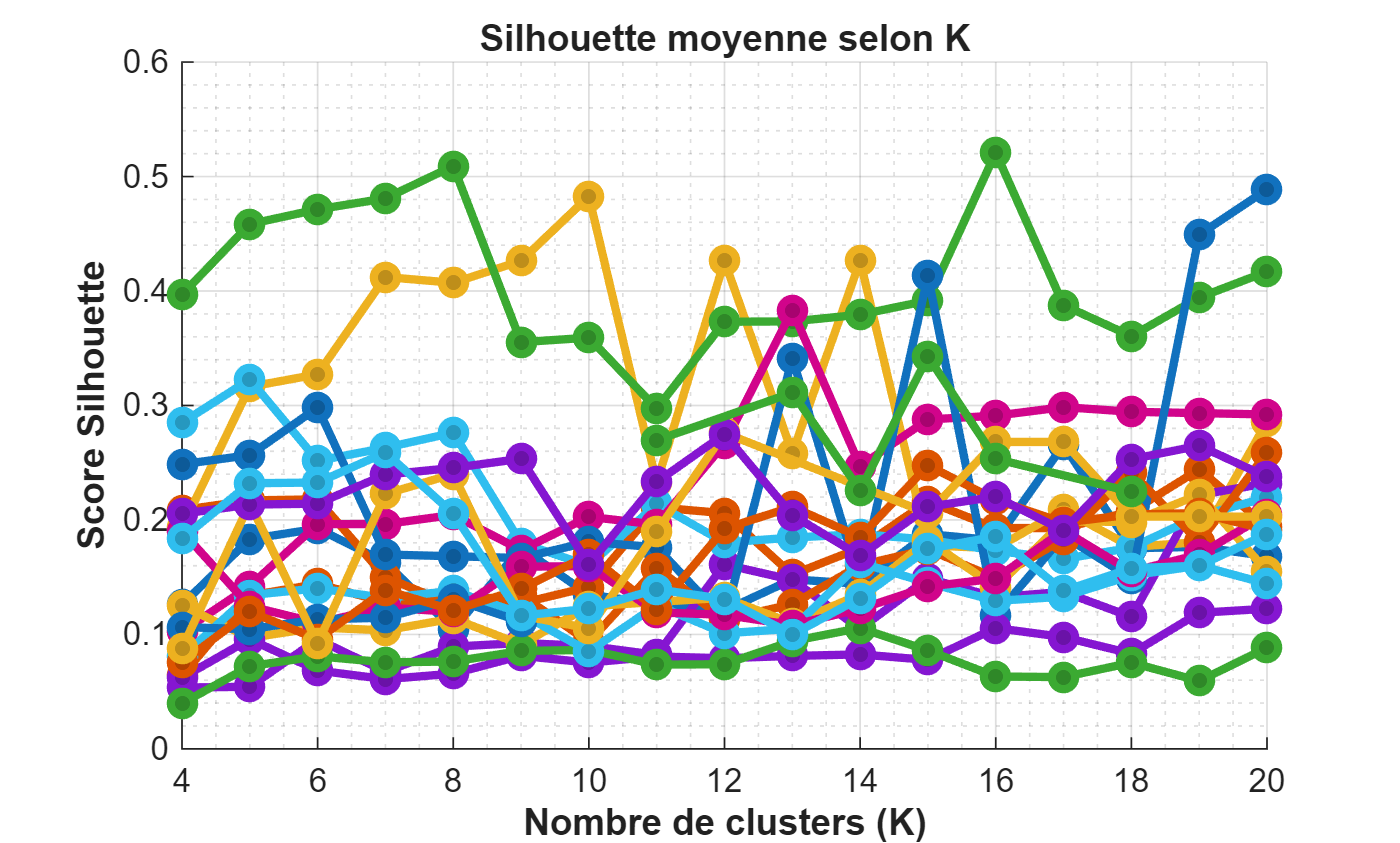


%% 7. GRAPHIQUES : Silhouette et Score Global vs K (TRIÉS PAR K CROISSANT)
figure('Name', 'Analyse des métriques par K', 'Color', 'w', 'Position', [100 100 1200 600]);

sessionFields = fieldnames(SessionsData);
colors = lines(length(sessionFields));

% --- GRAPHIQUE 1 : Silhouette moyenne en fonction de K ---
figure
hold on;
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2
        [K_sorted, idx_sort] = sort(sess.K);
        Silh_sorted = sess.Silh(idx_sort);
        plot(K_sorted, Silh_sorted, '-o', 'Color', colors(s,:), 'LineWidth', 2.5, ...
            'MarkerSize', 7, 'MarkerFaceColor', colors(s,:)*0.8, ...
            'DisplayName', sess.OriginalName);
    end
end
xlabel('Nombre de clusters (K)', 'FontWeight', 'bold');
ylabel('Score Silhouette', 'FontWeight', 'bold');
title('Silhouette moyenne selon K');
grid on; grid minor;
%legend('Location', 'best', 'Interpreter', 'none', 'FontSize', 8);
hold off;
nom_graph = fullfile(dossier_mere, 'silhouette.png');
saveas(gcf, nom_graph);

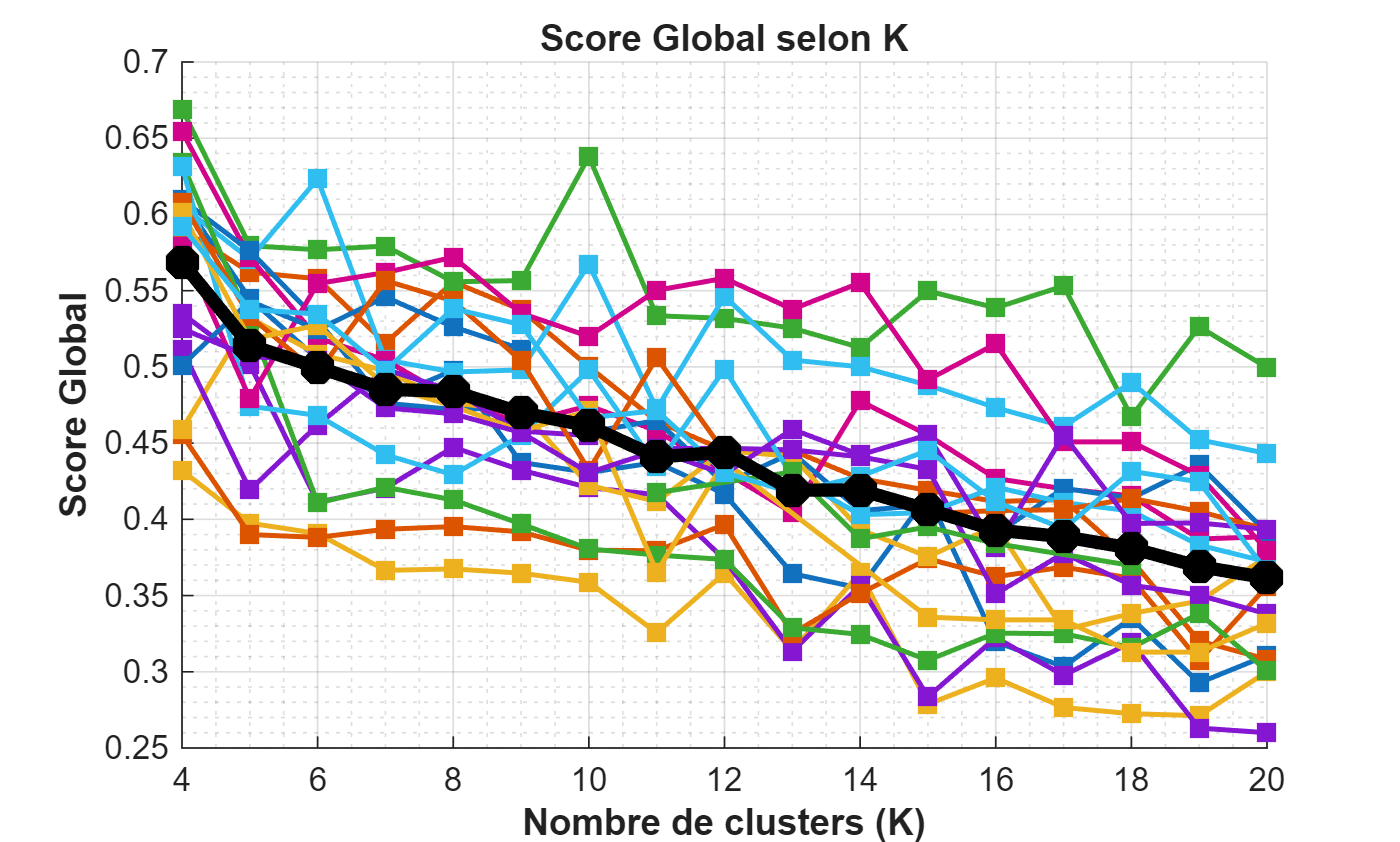

% --- GRAPHIQUE 2 : Score Global en fonction de K ---
figure
hold on;

% 1. On trace d'abord toutes les sessions individuelles
all_k_for_mean = [];
all_scores_for_mean = [];

for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if isfield(sess, 'Scores') && length(sess.K) >= 2
        [K_sorted, idx_sort] = sort(sess.K);
        Scores_sorted = sess.Scores(idx_sort);
        
        % On accumule les données pour le calcul de la moyenne plus tard
        all_k_for_mean = [all_k_for_mean, K_sorted];
        all_scores_for_mean = [all_scores_for_mean, Scores_sorted];
        
        % Tracé individuel
        plot(K_sorted, Scores_sorted, '-s', 'Color', [colors(s,:) 0.4], 'LineWidth', 1.5, ...
            'MarkerSize', 6, 'MarkerFaceColor', colors(s,:), ...
            'DisplayName', sess.OriginalName);
    end
end

% 2. Calcul et tracé de la courbe moyenne
if ~isempty(all_k_for_mean)
    unique_k = unique(all_k_for_mean);
    mean_scores = zeros(1, length(unique_k));
    
    for idx_k = 1:length(unique_k)
        current_k_val = unique_k(idx_k);
        % Moyenne de tous les scores obtenus pour ce K précis
        mean_scores(idx_k) = mean(all_scores_for_mean(all_k_for_mean == current_k_val), 'omitnan');
    end
    
    % Tracé de la moyenne en noir et épais pour qu'elle ressorte
    plot(unique_k, mean_scores, '-k*', 'LineWidth', 4, 'MarkerSize', 10, ...
        'DisplayName', 'Moyenne Globale');
end

xlabel('Nombre de clusters (K)', 'FontWeight', 'bold');
ylabel('Score Global', 'FontWeight', 'bold');
title('Score Global selon K');
grid on; grid minor;
% legend('Location', 'best', 'Interpreter', 'none', 'FontSize', 8);
hold off;

nom_graph = fullfile(dossier_mere, 'Score_global_K.png');
saveas(gcf, nom_graph);

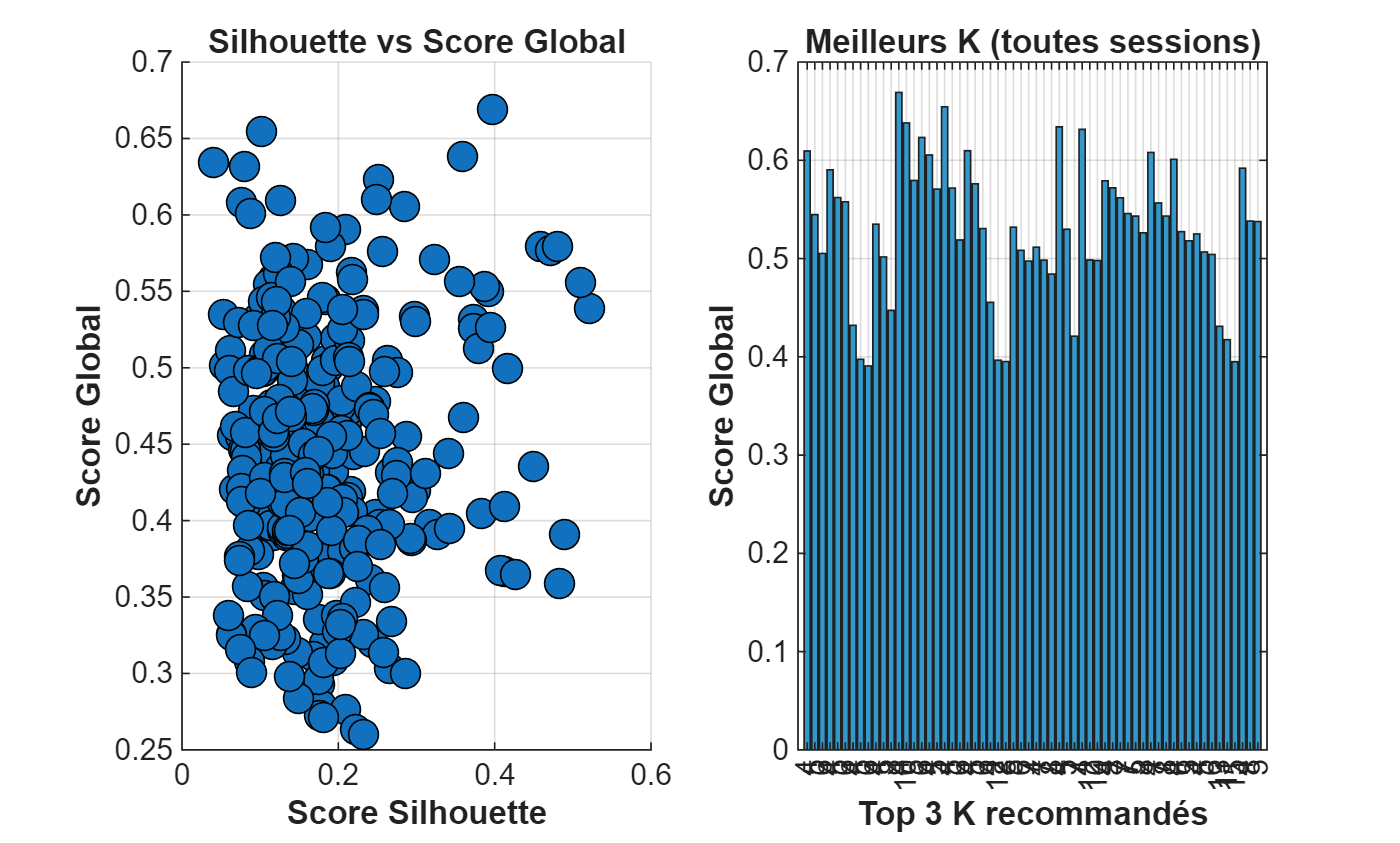



% --- GRAPHIQUE 3 : Silhouette vs Score Global (scatter) ---
figure;
subplot(1, 2, 1);
hold on;
all_silh = [];
all_scores = [];
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2
        all_silh = [all_silh, sess.Silh];
        all_scores = [all_scores, sess.Scores];
    end
end
scatter(all_silh, all_scores, 80, 'filled', 'MarkerEdgeColor', 'k');
xlabel('Score Silhouette', 'FontWeight', 'bold');
ylabel('Score Global', 'FontWeight', 'bold');
title('Silhouette vs Score Global');
grid on;
hold off;

% --- GRAPHIQUE 4 : Top 3 K recommandés ---
subplot(1, 2, 2);
top3_k = [];
top3_scores = [];
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2 && isfield(sess, 'Scores')
        [~, sortIdx] = sort(sess.Scores, 'descend');
        top3_k = [top3_k, sess.K(sortIdx(1:min(3, end)))];
        top3_scores = [top3_scores, sess.Scores(sortIdx(1:min(3, end)))];
    end
end
if ~isempty(top3_k)
    bar(1:length(top3_k), top3_scores, 'FaceColor', [0.2 0.6 0.8]);
    xticks(1:length(top3_k));
    xticklabels(arrayfun(@num2str, top3_k, 'UniformOutput', false));
    xlabel('Top 3 K recommandés', 'FontWeight', 'bold');
    ylabel('Score Global', 'FontWeight', 'bold');
    title('Meilleurs K (toutes sessions)');
    grid on;
end

% Sauvegarde globale
nom_graph = fullfile(dossier_mere, 'Analyse_Performance_K.png');
saveas(gcf, nom_graph);

fprintf('Graphique sauvegardé : %s\n', nom_graph);

Graphique sauvegardé : E:\Data\Aurelie\analysis\Final\assembly\nocues\Analyse_Performance_K.png




%% 8. FONCTION LOCALE (POUR LA WAITBAR DU PARFOR)
% Doit obligatoirement être tout à la fin du fichier
function updateWaitbar(h, total)
    persistent count;
    if isempty(count), count = 0; end
    count = count + 1;
    if isgraphics(h)
        waitbar(count / total, h, sprintf('Analyse Parallèle : %d/%d', count, total));
    end
    if count == total, count = []; end % Reset à la fin
end